x = linspace(-10, 10)

x =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


y = sin(x) + 0.05*x.^2

y =     5.5440    5.1646    4.7745    4.3815    3.9938    3.6196    3.2666    2.9419    2.6516    2.4004    2.1918    2.0276    1.9081    1.8317    1.7955    1.7950    1.8243    1.8767    1.9444    2.0195    2.0938    2.1592    2.2083    2.2344    2.2320    2.1969    2.1263    2.0192    1.8760    1.6989    1.4918    1.2596    1.0086    0.7461    0.4800    0.2183   -0.0307   -0.2592   -0.4602   -0.6273   -0.7558   -0.8419   -0.8837   -0.8808   -0.8345   -0.7476   -0.6246   -0.4711   -0.2938   -0.1003


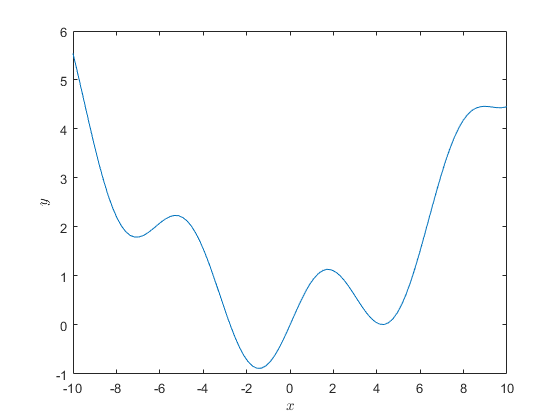

plot(x,y)

xlabel("$x$", "Interpreter","latex")
ylabel("$y$", "Interpreter","latex")


a = fsolve(@(x) cos(x) + 0.1*(x), -1.4)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


a = -1.4276

clipboard("copy", a)


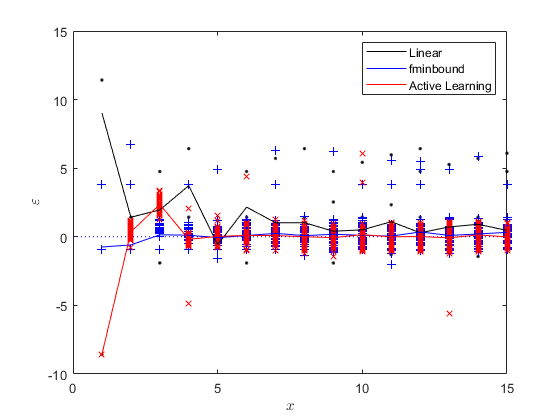

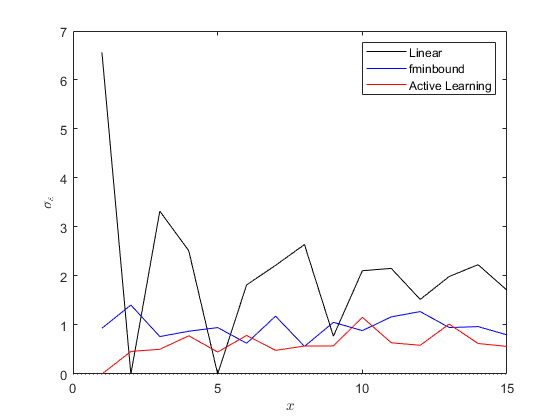

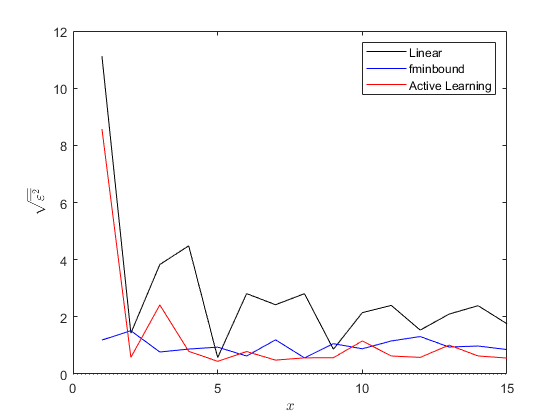

clear
comp = {};
comp{1, 1} = readmatrix("epsilon_linspace.csv");
comp{2, 1} = readmatrix("epsilon_fmin.csv");
comp{3, 1} = readmatrix("epsilon_aLearning.csv");

colour = ["k.", "b+", "rx"];
style = ['', "-", "-", "-"];
ylabels = ["\varepsilon", "{\varepsilon}", "\sigma_\varepsilon", "\sqrt{\overline{\varepsilon^{2}}}"];
for i = 1:size(comp, 1)
    comp{i, 2} = mean(comp{i,1}, 2);
    comp{i, 3} = sqrt(var(comp{i,1}, 0, 2));
    comp{i, 4} = sqrt(mean(comp{i,1}.^2, 2));
end
fig = zeros([1, size(comp, 2)]);
leg = "off";
figure(2)
for i = 1:size(comp, 2)
    if i ~= 2
        figure(i);
        plot([0 15], [0 0], 'b:', "HandleVisibility","off")
    else
        leg = "on";
        colour = ["k", "b", "r"];
    end
    hold on
    for j = 1:size(comp,1)
        opt = colour(j) + style(i);
        plot(comp{j, i}, opt, "HandleVisibility",leg)
    end
    xlabel("$x$", "Interpreter","latex")
    ylabel("$"+ylabels(i)+"$", "Interpreter","latex")
    legend("Linear", "fminbound", "Active Learning")
    hold off;
end

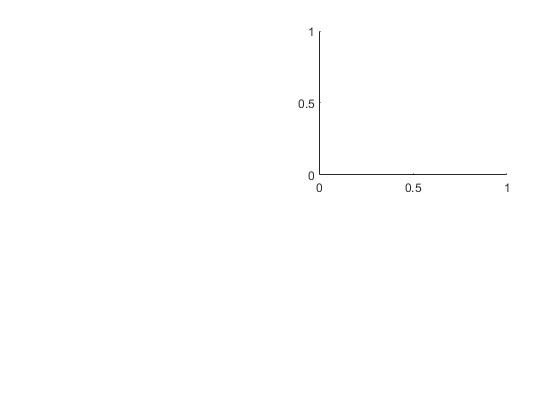

subplot(2,2,1)
figure(3)
subplot(2,2,2)

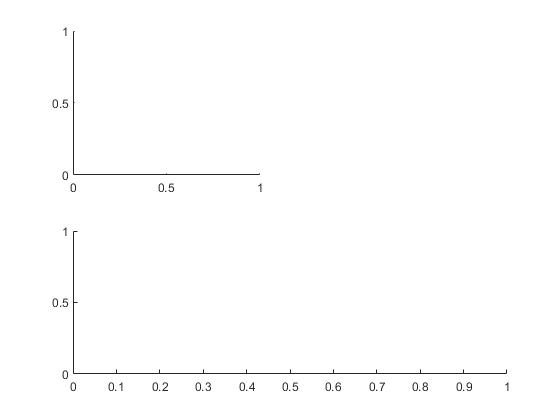

figure(4)
subplot(2,1,2)

figure(5)

a

a =   Figure (6) with properties:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties
